# Example 5.2: FMCW Radar

Nicholas O'Donoughue 1 July 2019

*Consider a frequency-modulated continuous wave  (FMCW) radar that dwells on a given frequency for *$$T_{\mathrm{hop}}= 1$$* ms, occupies *$$B_s=10$$* MHz of bandwidth, and may hop over any frequency between 8 and 12 GHz (*$$B_{\mathrm{hop}}=4$$* GHz).*

*What receiver bandwidth is required to adequately find this signal on every hop if we desire a frequency resolution equal to the transmit bandwidth (*$$\delta_f = B_s$$*)?  What if we desire *$$\delta_f$$*= 100 kHz?*

## Solution

First, we define the parameters of interest.

Thop_ms = [1, 0.1, 0.01]'; % ms
Bhop_MHz = 4000; % MHz
Bs_low_MHz = 0.1; % MHz
Bs_high_MHz = 10;% MHz
Bs_step_MHz = 0.1;% MHz

Thop = Thop_ms / 1e3;
Bhop = Bhop_MHz * 1e6;
Bs = (Bs_low_MHz:Bs_step_MHz:Bs_high_MHz)*1e6;

Then, we compute how long we must dwell on each frequency in order to obtain a resolution at least as small as the radar's channel size $$B_s = 10$$ MHz. This results in $$T_{\mathrm{dwell}}\geq 100$$ ns. From this, the number of scans that can be tolerated is

Tdwell = 1./Bs;
Ndwell = floor(Thop./Tdwell);

We can compute the allowable receiver bandwidth as the ratio of band of interest (such as the target signal's hopping bandwidth) divided by the number of scans that can fit within the hopping period. The receiver bandwidth should also be at least as large as the desired frequency resolution.

Br = max(Bs,Bhop./Ndwell);

In this case, the result is $$B_r = \delta_f = 10$$ MHz. The figure below plots the required receiver bandwidth as a function of desired channel size for various hopping rates. Note that, as the desired frequency resolution increases, the required receiver bandwidth decreases (to a point). This is because the larger frequency resolution dictates a shorter dwell time and allows more scans to occur within the required hopping period.  This inflection occurs when $$\delta_f = B_{\mathrm{scan}}/N_{\mathrm{dwell}}$$; beyond that point $$\delta_f$$ begins the driving force and (eventually) $$B_r$$ is independent of the hopping period

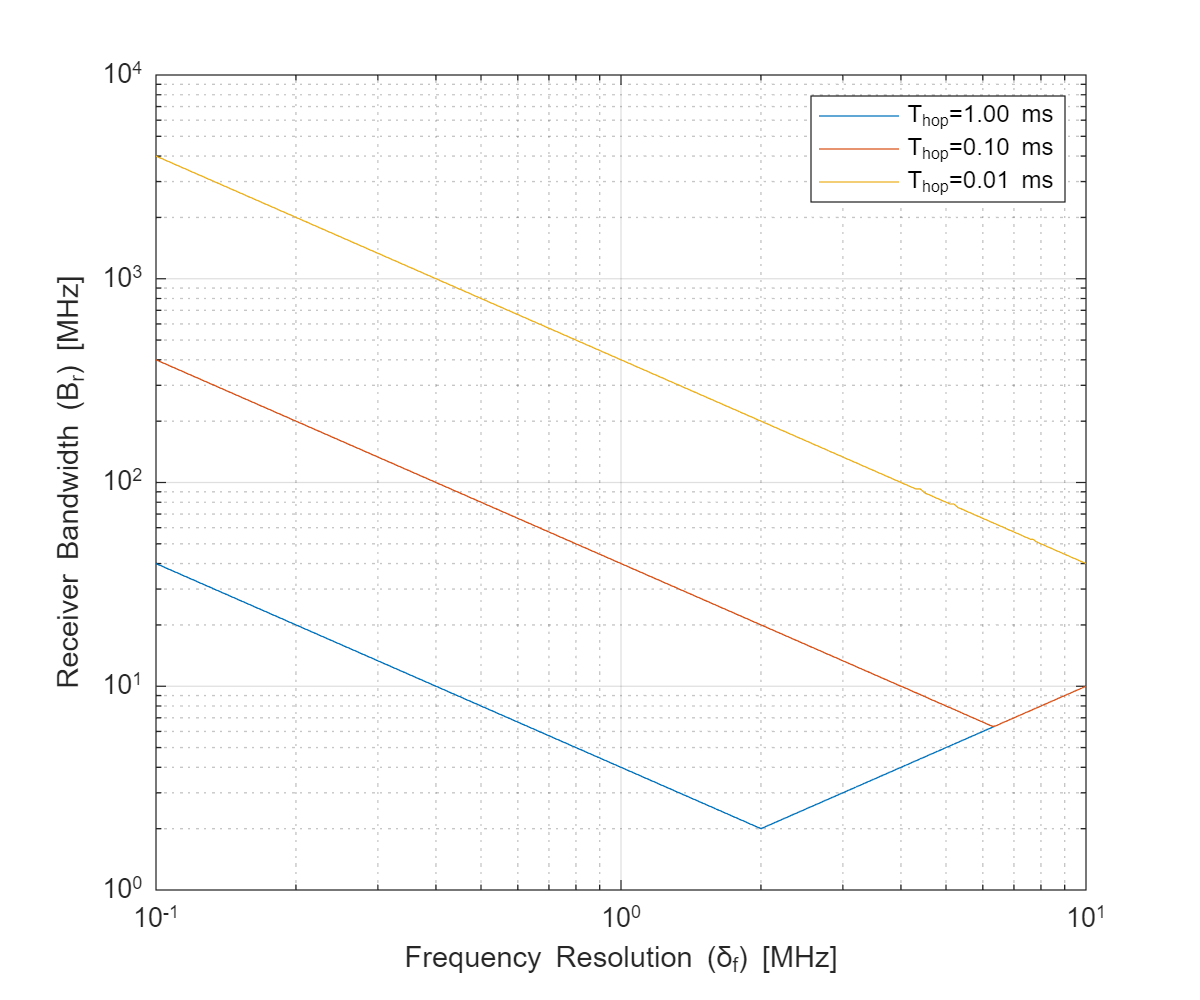

fig=figure;
loglog(Bs/1e6,Br/1e6);
xlabel('Frequency Resolution (\delta_f) [MHz]');
ylabel('Receiver Bandwidth (B_r) [MHz]');
legend(arrayfun(@(x) sprintf('T_{hop}=%.2f ms',x*1e3),Thop,'UniformOutput',false));
grid on;

At the specified hopping rate, $$T_{\mathrm{hop}}=1$$ ms, we can confirm the calculation already discussed, $$B_r \geq 10$$ MHz. To achieve a frequency resolution of $$\delta_f=$$ 100 kHz, the receiver bandwidth must now be $$B_r \geq 40$$ MHz. Notice that, as the hopping period $$T_{\mathrm{hop}}$$ decreases, the bandwidth must increase. This is because the receiver has fewer collection opportunities ($$N_{\mathrm{dwell}}$$), and so each dwell must collect a larger portion of the hopping band.

Recall that these calculations ignore the detectability constraint on dwell time\index{receiver!dwell period} (the minimum dwell time required to achieve the desired $$P_{\mathrm{D}}$$ for a given $$P_{\mathrm{FA}}$$).